# Plot summary of specified experiment

## Initialize

pfisrBaseDir = '20110121.001_bc_2min-Ne-cal.h5';
pfisrExpH5Str = 'G:\My Drive\Research\Projects\Paper 2\Data\Events List\';
storeImageDir = 'G:\My Drive\Research\Projects\Paper 2\Data\Events List\';
% setStoreImage = true;
% setPlotTimeLim = false;
% tTick = 4;
setPlotTimeLim = true;
minHrStr = '09:00';
maxHrStr = '15:00';
tTick =0.5;

## Extract data

amisrData=read_amisr(strcat(pfisrExpH5Str,pfisrBaseDir));
midTime = median(amisrData.time(1,:));
omniDateStr = datestr(midTime,'dd mmm yyyy');
download_omni_cdf(omniDateStr,'C:\Users\nithin\Documents\GitHub\LargeFiles\','cdf');
[omniData, omniDilePath] = process_omni_data(omniDateStr,...
    'C:\Users\nithin\Documents\GitHub\LargeFiles\',false);

ne = squeeze(amisrData.electronDensity(:,amisrData.magBeamNo,:));
ne(ne<=0) = 10^3;
plotData(1) = generate_plot_data(amisrData.time(1,:),amisrData.altitude(:,amisrData.magBeamNo),...
    {log10(ne)},'auto',[60 120],{[8 12]},'auto',{'Ne along B-field';'[km]'},{'log10 m-3'},'2D');

neAvg = squeeze(mean(amisrData.electronDensity,2));
neAvg(neAvg<=0) = 10^3;
plotData(2) = generate_plot_data(amisrData.time(1,:),amisrData.altitude(:,amisrData.magBeamNo),...
    {log10(neAvg)},'auto',[60 120],{[8 12]},'auto',{'Ne avg across beams';'[km]'},{'log10 m-3'},'2D');

plotData(3) = generate_plot_data(omniData.minutely.time,omniData.minutely.maginput(:,17),...
    {[]},'auto',[-1000 0],{[]},'auto',{'AL - index';'[nT]'},{[]},'1D');

horzAxisData.x = amisrData.time(1,:);
horzAxisData.y = mod((horzAxisData.x-floor(horzAxisData.x))*24+(266-72.63)/15,24);
horzAxisData.label = 'PFISR MLT [hr]';

## Plot Image

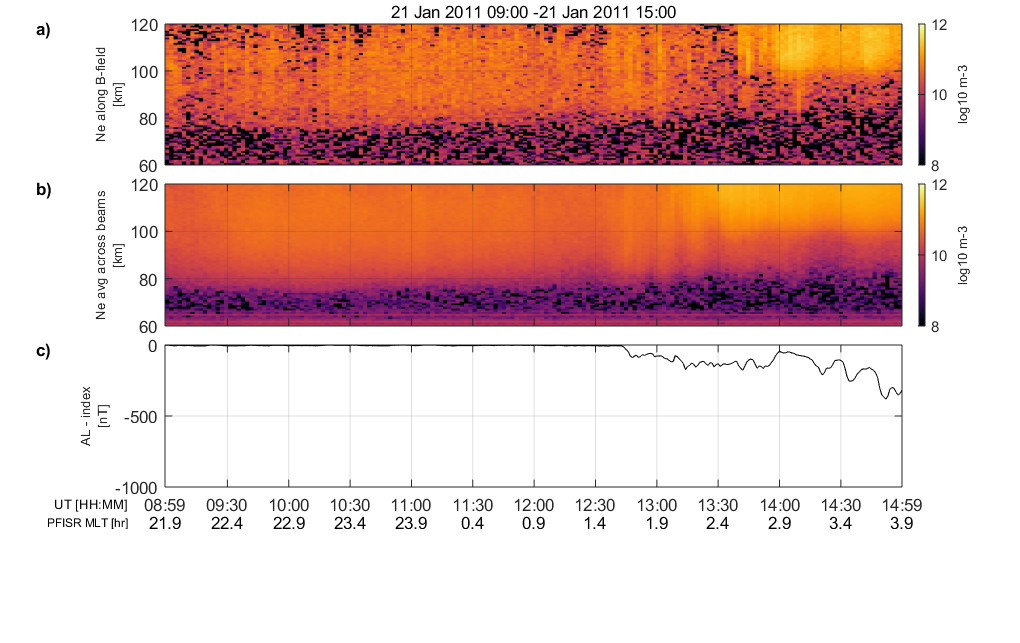

if setPlotTimeLim == true
    timeMinLimStr = [omniDateStr,' ',minHrStr];
    timeMaxLimStr = [omniDateStr,' ',maxHrStr];
else
    timeMinLimStr = datestr(min(amisrData.time(1,:))); 
    timeMaxLimStr=datestr(max(amisrData.time(1,:)));
end

figureHandle=plot_data_panels(plotData,horzAxisData,amisrData.time(1,:),timeMinLimStr,timeMaxLimStr,tTick);

## Store Image

imageName = [datestr(datenum(timeMinLimStr),'dd_mmm_yyyy_hh_MM'),'_to_',datestr(datenum(timeMaxLimStr),'dd_mmm_yyyy_hh_MM'),'_highres'];
if setStoreImage == true
    export_fig(strcat(storeImageDir,imageName,'.png'),'-r300','-png','-nocrop');
    close(figureHandle);
end
    

function hFig=plot_data_panels(data,horzAxisData,primaryTime,timeMinStr,timeMaxStr,timeTick,titleStr)
      
    nData = length(data);
    nPanel = nData;
    
    hFig = figure(1);
    
    clf
    
    p=panel();
    p.pack(1);
    
    panelSize = 30; % in mm
    demargin = 4;
    panelDefinition=cell(1,nPanel);
    for i=1:1:nPanel
        panelDefinition(i)={{panelSize}}; 
    end
    p(1).pack(panelDefinition);
    
    p.marginleft=35;
    p.marginright=25;
    p(1).de.margin=demargin;
    % p.fontsize=12;
    p.select('all');
    
    if isempty(timeMinStr)
        timeMinStr  = datestr(min(primaryTime));
    end
    if isempty(timeMaxStr)
        timeMaxStr = datestr(max(primaryTime));
    end
    
    if nargin<7 || isempty(titleStr)
        titleStr = strcat(timeMinStr,' - ',timeMaxStr);
    end
    
    if nargin<6 || isempty(timeTick)
        timeTick = 0.5;
    end
    
    resize_figure(hFig, panelSize*nPanel+4*(nPanel+1)+30);
    
    q=p(1);
    k=1;
    
    for thisData=1:1:nData
        q(k).select();
        text(-0.175,0.975,[char(96+k),')'],'Units','normalized','FontWeight','bold');
        hold on;
        if(thisData==1)
            title(titleStr);
        end
        if data(thisData).mode=='2D'
            plot_2D_time_series(data(thisData).x,data(thisData).y,cell2mat(data(thisData).z),...
                timeTick,0,timeMinStr,timeMaxStr);
            label_time_axis(data(thisData).x, false, timeTick,timeMinStr,timeMaxStr);
            grid on;
            
            % Setting up yaxis
            set(gca,'Yscale','linear','YLim',data(thisData).ylim);
            
            % Setting up the colorbar
            % Making sure the color bar will be outside the axes
            axPos = get(gca, 'position');
            colormap(inferno);
 
            c=colorbar('eastoutside','YLim',cell2mat(data(thisData).zlim));
            caxis(cell2mat(data(thisData).zlim));
 
            ylabel(c,data(thisData).zlabel,'FontSize',8);
            c.TickLength=0.05;
            set(gca,'position',axPos);
            
            
            % reducing color bar thickness
            cPos=get(c,'Position');
            cPos(3)=0.2*cPos(3);
            set(c, 'Position',cPos);
                
        elseif data(thisData).mode == '1D'
            plot(data(thisData).x, data(thisData).y,'k');
            label_time_axis(data(thisData).x, false, timeTick, timeMinStr, timeMaxStr);
            set(gca,...
             'YLim',data(thisData).ylim);
         %             'YTick','auto',...
%              'YTickLabel','auto',...
             grid on;    
            
        end
        q(k).fontsize=10;
        ylabel(data(thisData).ylabel,'FontSize',8);
        
        %(data(thisData).label));
        hold on;
        k=k+1;
        box on;
    end
    label_time_axis(primaryTime, true, timeTick, timeMinStr, timeMaxStr);
    [TTick, DateNumBeg, DateNumEnd] = get_axes_time_tick_values( primaryTime, timeTick, timeMinStr, timeMaxStr );
    TTickLim=[DateNumBeg DateNumEnd];
    if ~isempty(horzAxisData)
        
        nHorzAxis = length(horzAxisData);
        for thisAxis = 1:1:nHorzAxis
            add_horizontal_axes( TTick, TTickLim, horzAxisData.x, horzAxisData.y, horzAxisData.label, thisAxis+1);
        end
    end
    set(gcf,'color','w');
end

function data = generate_plot_data(x,y,z,xlim,ylim,zlim,xlabel,ylabel,zlabel,mode)
    
    if nargin<10
        data.mode = '2D';
    else
        data.mode = mode;
    end
    
    data.x = x;
    data.y = y;
    data.xlim = xlim;
    data.ylim = ylim;
    data.xlabel = xlabel;
    data.ylabel = ylabel;
    if ~isempty(z)
        data.z = z;
        data.zlim = zlim;
        data.zlabel =zlabel;
    end
end